Gs = (10)/((s+2)*(s+p1))

$$Gs = \frac{10}{\left(p_{1}+s\right)\,\left(s+2\right)}$$

Ts = Gs/(1+Gs)

$$Ts = \frac{10}{\left(p_{1}+s\right)\,\left(\frac{10}{\left(p_{1}+s\right)\,\left(s+2\right)}+1\right)\,\left(s+2\right)}$$

Ts = collect(Ts,p1)

$$Ts = \frac{10}{\left(s+2\right)\,p_{1}+s^{2}+2\,s+10}$$

KGsHs= (s+2)/(s^2+2*s+10)

$$KGsHs = \frac{s+2}{s^{2}+2\,s+10}$$

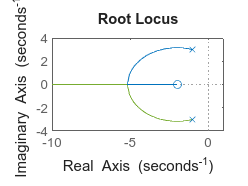

[num,den] = numden(KGsHs);
sys = tf(sym2poly(num),sym2poly(den));
rlocus(sys)

%ch8 generalized rl problem
syms s p1
Gs = 100/(s*(s+p1))

$$Gs = \frac{100}{s\,\left(p_{1}+s\right)}$$

Ts = Gs/(1+Gs)

$$Ts = \frac{100}{s\,\left(\frac{100}{s\,\left(p_{1}+s\right)}+1\right)\,\left(p_{1}+s\right)}$$

Ts = collect(Ts,p1)

$$Ts = \frac{100}{s\,p_{1}+s^{2}+100}$$

GsHs = s / (s^2+100)

$$GsHs = \frac{s}{s^{2}+100}$$

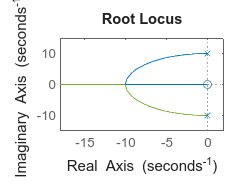

[num,den] = numden(GsHs);
sys = tf(sym2poly(num),sym2poly(den));
rlocus(sys)

Chapter 8.9 ~ Changing from negative feedback systems to positive feedback systems.

Gs = ((s+3))/(s*(s+1)*(s+2)*(s+4))

$$Gs = \frac{s+3}{s\,\left(s+1\right)\,\left(s+2\right)\,\left(s+4\right)}$$

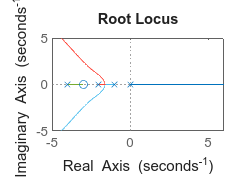

negativeKGsHs = -Gs;
[num,den] = numden(negativeKGsHs);
sys = tf(sym2poly(num),sym2poly(den));
rlocus(sys)

Chapter 8.10 - Pole Sensitivity

$$Ts = s^{2}+10\,s+K$$

$$dsdk = 2\,s+10$$


s =
 
  s
 
Continuous-time transfer function.
Model Properties



Gs =
 
             1
  ------------------------
  s^3 + 13 s^2 + 32 s + 20
 
Continuous-time transfer function.
Model Properties


K = 164.6000


GsK =
 
           164.6
  ------------------------
  s^3 + 13 s^2 + 32 s + 20
 
Continuous-time transfer function.
Model Properties



Ts =
 
              164.6 s^3 + 2140 s^2 + 5267 s + 3292
  ------------------------------------------------------------
  s^6 + 26 s^5 + 233 s^4 + 1037 s^3 + 3684 s^2 + 6547 s + 3692
 
Continuous-time transfer function.
Model Properties


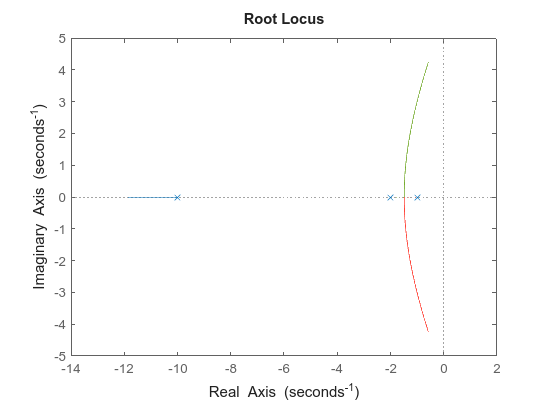

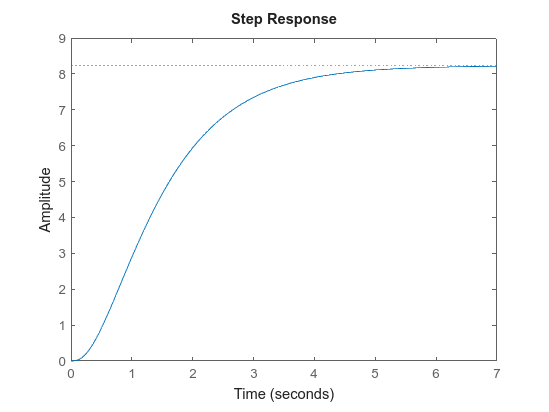


sys =
 
             1
  ------------------------
  s^3 + 13 s^2 + 32 s + 20
 
Continuous-time transfer function.
Model Properties


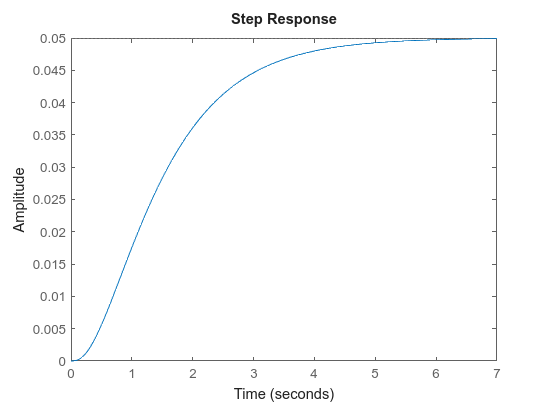

$$Gs = \frac{K}{\left(s+1\right)\,\left(s+2\right)\,\left(s+10\right)}$$

$$den = \left(s+1\right)\,\left(s+2\right)\,\left(s+10\right)$$

$$ans = s^{3}+13\,s^{2}+32\,s+20$$

syms K s
Ts =(s^2 + 10*s +K)

dsdk = diff(Ts,s)

Chapter 9.2 - Compensators

clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs = 1/ ((s+1)*(s+2)*(s+10))


Gs =
 
             1
  ------------------------
  s^3 + 13 s^2 + 32 s + 20
 
Continuous-time transfer function.
Model Properties


K=164.6

K = 164.6000

GsK = K / ((s+1)*(s+2)*(s+10))


GsK =
 
           164.6
  ------------------------
  s^3 + 13 s^2 + 32 s + 20
 
Continuous-time transfer function.
Model Properties


Ts = GsK / (1+GsK)


Ts =
 
              164.6 s^3 + 2140 s^2 + 5267 s + 3292
  ------------------------------------------------------------
  s^6 + 26 s^5 + 233 s^4 + 1037 s^3 + 3684 s^2 + 6547 s + 3692
 
Continuous-time transfer function.
Model Properties


rlocus(Gs, linspace(0, 200, 10e4))

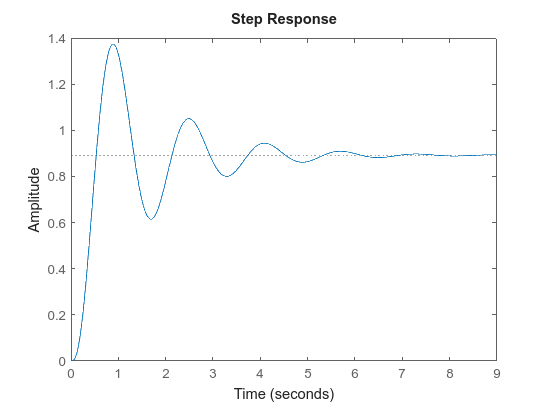

step(Ts)

r = stepinfo(Ts)

r = struct with fields:
         RiseTime: 0.3200
    TransientTime: 5.1382
     SettlingTime: 5.1382
      SettlingMin: 0.6149
      SettlingMax: 1.3737
        Overshoot: 54.0646
       Undershoot: 0
             Peak: 1.3737
         PeakTime: 0.8883


%compensated system
clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs = 1/ ((s+1)*(s+2)*(s+10))


Gs =
 
             1
  ------------------------
  s^3 + 13 s^2 + 32 s + 20
 
Continuous-time transfer function.
Model Properties


K=158.2

K = 158.2000

Gs = (K*(s+0.1) / (s)) * Gs


Gs =
 
        158.2 s + 15.82
  ----------------------------
  s^4 + 13 s^3 + 32 s^2 + 20 s
 
Continuous-time transfer function.
Model Properties


Ts = Gs/(1+Gs)


Ts =
 
              158.2 s^5 + 2072 s^4 + 5268 s^3 + 3670 s^2 + 316.4 s
  ----------------------------------------------------------------------------
  s^8 + 26 s^7 + 233 s^6 + 1030 s^5 + 3616 s^4 + 6548 s^3 + 4070 s^2 + 316.4 s
 
Continuous-time transfer function.
Model Properties


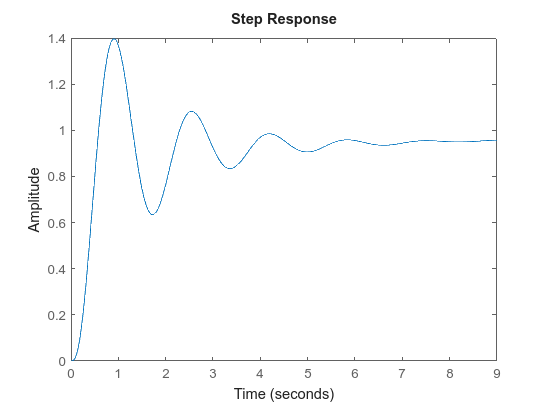

step(Ts,9)

r = stepinfo(Ts)

r = struct with fields:
         RiseTime: 0.3538
    TransientTime: 17.8115
     SettlingTime: 17.8115
      SettlingMin: 0.6343
      SettlingMax: 1.3964
        Overshoot: 39.6440
       Undershoot: 0
             Peak: 1.3964
         PeakTime: 0.9087


%skill assessment 9.1
clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs = 1/(s*(s+7))


Gs =
 
      1
  ---------
  s^2 + 7 s
 
Continuous-time transfer function.
Model Properties


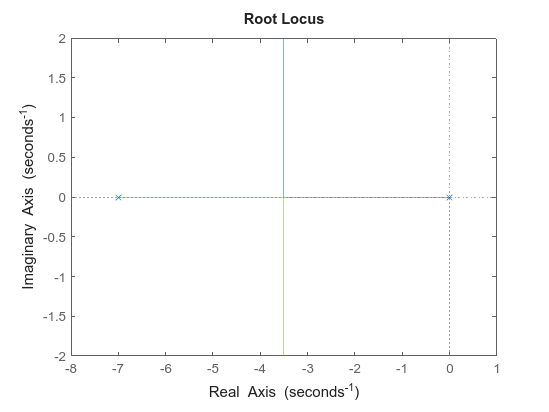

rlocus(Gs)

K=47.4

K = 47.4000

Gs= K*Gs


Gs =
 
    47.4
  ---------
  s^2 + 7 s
 
Continuous-time transfer function.
Model Properties


%example 9.3
clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs = 1/(s*(s+4)*(s+6))


Gs =
 
           1
  -------------------
  s^3 + 10 s^2 + 24 s
 
Continuous-time transfer function.
Model Properties


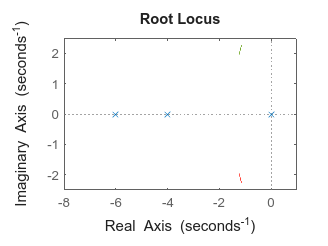

rlocus(Gs, linspace(40,50,1e4))

%ex 9.3 uncomp
damp = 0.504

damp = 0.5040

natfreq = (4*9)/(10*damp)

natfreq = 7.1429


rl = -natfreq*damp

rl = -3.6000

imag = natfreq * sqrt(1-damp^2)

imag = 6.1693

out = checkRootLocusAngle(Gs, rl+imag*i)

out = struct with fields:
    sum: -275.2981
    mod: 84.7019


R = (imag - (-rl*tand(out.mod)))/(-tand(out.mod))

R = 3.0279

newGs = Gs*(s-3)


newGs =
 
         s - 3
  -------------------
  s^3 + 10 s^2 + 24 s
 
Continuous-time transfer function.
Model Properties


Ts = Gs/(1+Gs)


Ts =
 
                 s^3 + 10 s^2 + 24 s
  -------------------------------------------------
  s^6 + 20 s^5 + 148 s^4 + 481 s^3 + 586 s^2 + 24 s
 
Continuous-time transfer function.
Model Properties


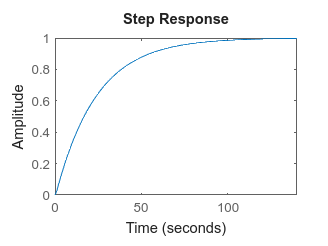

step(Ts) % ah shit this is missing K

%example 9.4
clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs = 1/(s*(s+4)*(s+6))


Gs =
 
           1
  -------------------
  s^3 + 10 s^2 + 24 s
 
Continuous-time transfer function.
Model Properties


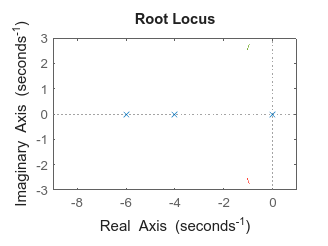

rlocus(Gs, linspace(59,69,1e4))

Ts = 3.9604

Ts = 3.9604

Ts2 = Ts/2

Ts2 = 1.9802

damping = 0.357

damping = 0.3570

natfreq = 4/(Ts2*damping)

natfreq = 5.6583

rl = -natfreq*damping

rl = -2.0200

imag = natfreq * sqrt(1-damping^2)

imag = 5.2854


CLpole = rl + imag*1j

CLpole = -2.0200 + 5.2854i

out = checkRootLocusAngle(Gs,CLpole)

out = struct with fields:
    sum: -233.3989
    mod: 126.6011


theta = -(out.sum +180)

theta = 53.3989

x = (imag + tand(theta)) / tand(theta)

Error using imag
Not enough input arguments.

Chapter 9.5 - feedback compensation

clear;
syms s K Kf
Gms = 1 / (s*(s+5)*(s+15))

$$Gms = \frac{1}{s\,\left(s+5\right)\,\left(s+15\right)}$$

Hms =  Kf*s

$$Hms = \mathrm{Kf}\,s$$

$$Gmu = \frac{1}{s\,\left(s+5\right)\,\left(s+15\right)\,\left(\frac{\mathrm{Kf}}{\left(s+5\right)\,\left(s+15\right)}-\frac{1}{s\,\left(s+5\right)\,\left(s+15\right)}+1\right)}$$

$$Gmu = \frac{1}{75\,s+\mathrm{Kf}\,s+20\,s^{2}+s^{3}-1}$$

Tmu = Gms / (1+Gms*Hms)

$$Tmu = \frac{1}{s\,\left(\frac{\mathrm{Kf}}{\left(s+5\right)\,\left(s+15\right)}+1\right)\,\left(s+5\right)\,\left(s+15\right)}$$

Tmu = simplify(Tmu)

$$Tmu = \frac{1}{s\,\left(s^{2}+20\,s+\mathrm{Kf}+75\right)}$$

clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gms = 1 / (s*(s+5)*(s+15))


Gms =
 
           1
  -------------------
  s^3 + 20 s^2 + 75 s
 
Continuous-time transfer function.
Model Properties


Hms =  s


Hms =
 
  s
 
Continuous-time transfer function.
Model Properties



openlptf = Hms *Gms


openlptf =
 
           s
  -------------------
  s^3 + 20 s^2 + 75 s
 
Continuous-time transfer function.
Model Properties


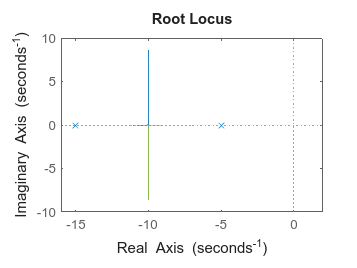

rlocus(openlptf, linspace(0,100,1e4))

clear;

s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Kf = 81.3

Kf = 81.3000

Gms = 1 / (s*(s+5)*(s+15))


Gms =
 
           1
  -------------------
  s^3 + 20 s^2 + 75 s
 
Continuous-time transfer function.
Model Properties


Hms =  Kf *s


Hms =
 
  81.3 s
 
Continuous-time transfer function.
Model Properties


GFL = Gms / (1+Gms*Hms)


GFL =
 
                 s^3 + 20 s^2 + 75 s
  --------------------------------------------------
  s^6 + 40 s^5 + 631.3 s^4 + 4626 s^3 + 1.172e04 s^2
 
Continuous-time transfer function.
Model Properties


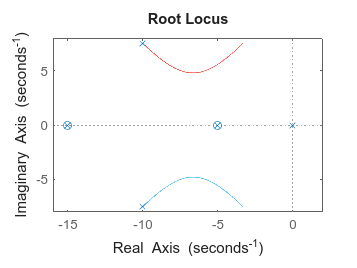

rlocus(GFL, linspace(0,900,1e4))

% BANG

clear;